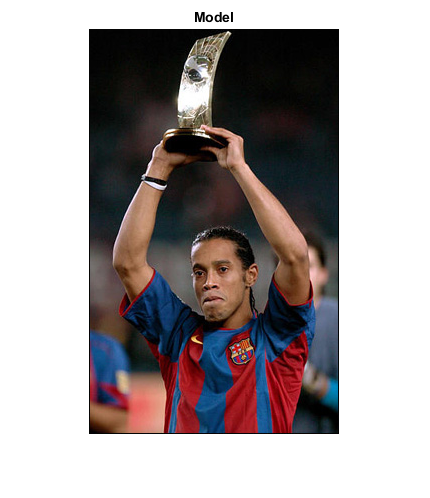

im = imread('model.jpg');
figure, imshow(im); title('Model');

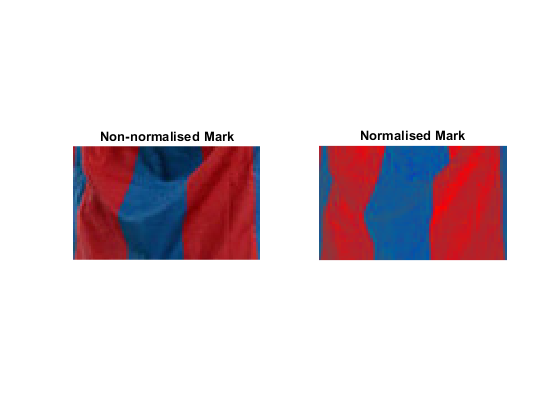


pattern = im(350:400,87:170,:);
figure, 
subplot(1,2,1);imshow(pattern); title('Non-normalised Mark');

imnorm = normalizeRGB(im);
pattnorm = imnorm(350:400,87:170,:);
subplot(1,2,2);imshow(pattnorm); title('Normalised Mark');

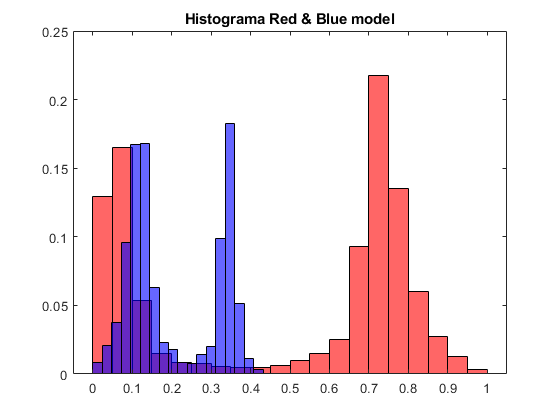


figure, [model_red, model_blue] = histRB(pattnorm, 20); title('Histograma Red & Blue model');


positive = imread('madrid/40.jpg');
posnorm = normalizeRGB(positive);
figure, [red, blue] = histRB(pattnorm, 20); title('Histograma Red & Blue model');


rmse = 0.1;
kldiv = 2.0;
index = 1;

[rmse kldiv] = computeQuadrants(pattnorm, posnorm, index, rmse, kldiv);
 